## Задание 1. Режекторная фильтрация: слежение.

function observable(C, A)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function controllable(A, B)
    Co = ctrb(A, B)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end
function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

A = [3 5 4;-2 -4 -5;2 2 3];
B = [2;-1;1];
C = [-2 -1 0];
D = 1;

Gamma_g = [0 5 0;-5 0 0;0 0 0];
Yg = [8 0 2];
wg0 = [1; 0; 1];
G = [1; 0; 1];

controllable(Gamma_g, G);

Co =      1     0   -25
     0    -5     0
     1     0     0


rank_Co = 3

YES


Abar = [Gamma_g -G*C; zeros(3, 3) A];
Bbar = [-G*D; B];
Gbar = [G; zeros(3, 1)];

eig(Abar)

ans =    0.0000 + 0.0000i
   0.0000 + 5.0000i
   0.0000 - 5.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i


analyze_controllability(Abar, Bbar);

Eigenvalues of A:
   0.0000 + 0.0000i
   0.0000 + 5.0000i
   0.0000 - 5.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =      0    -5     0    -2    -1     0    -1
     5     0     0     0     0     0     0
     0     0     0    -2    -1     0    -1
     0     0     0    -3    -5    -4     2
     0     0     0     2     4     5    -1
     0     0     0    -2    -2    -3     1


rank_H = 6

Eigenvalue 0 0i is controllable.


H =    0.0000 + 5.0000i  -5.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   5.0000 + 0.0000i   0.0000 + 5.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 5.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 + 5.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 + 5.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -3.0000 + 5.0000i   1.0000 + 0.0000i


rank_H = 6

Eigenvalue 0 5.000000e+00i is controllable.


H =    0.0000 - 5.0000i  -5.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   5.0000 + 0.0000i   0.0000 - 5.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 5.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 - 5.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 - 5.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -3.0000 - 5.0000i   1.0000 + 0.0000i


rank_H = 6

Eigenvalue 0 -5.000000e+00i is controllable.


H =    2.0000 + 1.0000i  -5.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   5.0000 + 0.0000i   2.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 1.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


rank_H = 6

Eigenvalue 2 1.000000e+00i is controllable.


H =    2.0000 - 1.0000i  -5.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   5.0000 + 0.0000i   2.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 - 1.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


rank_H = 6

Eigenvalue 2 -1.000000e+00i is controllable.


H =    -2.0000   -5.0000         0   -2.0000   -1.0000         0   -1.0000
    5.0000   -2.0000         0         0         0         0         0
         0         0   -2.0000   -2.0000   -1.0000         0   -1.0000
         0         0         0   -5.0000   -5.0000   -4.0000    2.0000
         0         0         0    2.0000    2.0000    5.0000   -1.0000
         0         0         0   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 5

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


[AJ, BJ, P] = j_stuff_B(Abar, Bbar);

Вещественная жорданова форма матрицы A:
     0     0     0     0     0     0
     0    -2     0     0     0     0
     0     0     2    -1     0     0
     0     0     1     2     0     0
     0     0     0     0     0    -5
     0     0     0     0     5     0

Вещественная P:
         0    0.0690   -0.0354   -0.1061         0    1.4142
         0    0.1724   -0.0354    0.2475    1.4142         0
    1.0000    0.5000    0.2828   -0.5657         0         0
         0   -1.0000    0.7071   -0.7071         0         0
         0    1.0000   -1.4142         0         0         0
         0         0    1.4142         0         0         0

Вещественная P^{-1}:
         0         0    1.0000   -0.8000   -1.3000   -1.1000
         0         0         0         0    1.0000    1.0000
         0         0         0         0         0    0.7071
         0         0         0   -1.4142   -1.4142   -0.7071
         0    0.7071         0    0.2475    0.1256    0.0195
    0.7071         0        

Aj = [   0     0     0     0     0;
         0     2    -1     0     0;
         0     1     2     0     0;
         0     0     0     0    -5;
         0     0     0     5     0];
Bj = [-2.4000;    0.7071;   -2.1213;    0.3889;   -0.8485];
poles = [-1 -3 -4 -5 -6];
Y1 = [1 1 1 1 1];
G1 = diag(poles);
observable(Y1, G1);

Ob =            1           1           1           1           1
          -1          -3          -4          -5          -6
           1           9          16          25          36
          -1         -27         -64        -125        -216
           1          81         256         625        1296


rank_Ob = 5

YES


cvx_begin sdp quiet;
    variable P1(5,5);
    Aj*P1-P1*G1 == Bj*Y1;
cvx_end;
Kj = -Y1*pinv(P1)

Kj =     1.2000  -39.5276    0.9192   -6.5425  -14.5249


KJ = [Kj(1, 1) 0 Kj(1, 2) Kj(1, 3) Kj(1, 4) Kj(1, 5)];
K=KJ/P

K =   -10.2706   -4.6262    1.2000   -2.3386   -1.4326  -28.8260


Kw = [K(1, 1) K(1, 2) K(1, 3)];
Kx = [K(1, 4) K(1, 5) K(1, 6)];
eig(Abar+Bbar*K)

ans =    -5.9692
   -5.0652
   -3.9539
   -3.0119
   -0.9999
   -2.0000


syms s
Cbar = [zeros(1, 3) C] + D*K;
I = eye(6);
W = -Cbar * (s*I - (Abar + Bbar*K))^(-1)*Gbar + 1;
simpW = simplify(W)

$$simpW = \frac{s\,\left(2535301200456458802993406410752\,s^{4}+71167366817516623055821031342080\,s^{3}+127722438477717116301490276794368\,s^{2}+1779184170437915892442122754557225\,s+1608497711657641159917992328753435\right)}{2535301200456458802993406410752\,s^{5}+48170558434376849663397520736256\,s^{4}+347344339781565219959288350375936\,s^{3}+1168771807500847442261568723453737\,s^{2}+1779815371024200819517456179979035\,s+912708432164359918852351098624000}$$

vpa(simpW, 4)

$$ans = \frac{s\,\left(2.535e+30\,s^{4}+7.117e+31\,s^{3}+1.277e+32\,s^{2}+1.779e+33\,s+1.608e+33\right)}{2.535e+30\,s^{5}+4.817e+31\,s^{4}+3.473e+32\,s^{3}+1.169e+33\,s^{2}+1.78e+33\,s+9.127e+32}$$

[num, den] = numden(simpW);
num = sym(num)

$$num = s\,\left(2535301200456458802993406410752\,s^{4}+71167366817516623055821031342080\,s^{3}+127722438477717116301490276794368\,s^{2}+1779184170437915892442122754557225\,s+1608497711657641159917992328753435\right)$$

den = sym(den)

$$den = 2535301200456458802993406410752\,s^{5}+48170558434376849663397520736256\,s^{4}+347344339781565219959288350375936\,s^{3}+1168771807500847442261568723453737\,s^{2}+1779815371024200819517456179979035\,s+912708432164359918852351098624000$$

solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} 0\\ -27.14\\ -0.9352\\ -5.0\,\mathrm{i}\\ 5.0\,\mathrm{i} \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -0.9999\\ -3.012\\ -3.954\\ -5.065\\ -5.969 \end{array}\right)$$

I=eye(3);
E = simpW*(Yg*(s*I-Gamma_g)^(-1)*wg0);
simpE = simplify(E);
vpa(simpE, 4)

$$ans = \frac{10.0\,\left(s^{2}+5.0\right)\,\left(2.535e+30\,s^{4}+7.117e+31\,s^{3}+1.277e+32\,s^{2}+1.779e+33\,s+1.608e+33\right)}{\left(s^{2}+25.0\right)\,\left(2.535e+30\,s^{5}+4.817e+31\,s^{4}+3.473e+32\,s^{3}+1.169e+33\,s^{2}+1.78e+33\,s+9.127e+32\right)}$$


var = vpa(limit(s*simpE,s,0), 4)

$$var = 0.0$$

e0_bar = zeros(6,1);
model_name = 'task1';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(5));

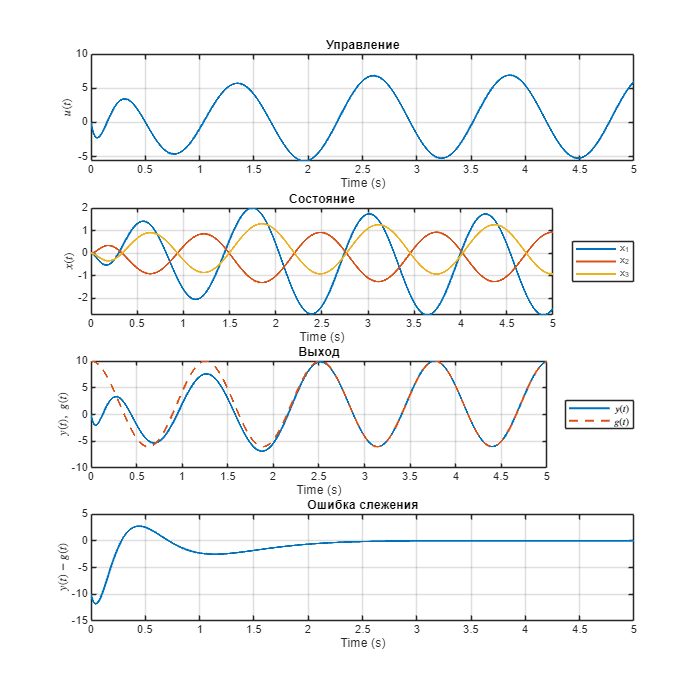

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
ylabel('$x(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(out.y, 'LineWidth', 1.5); hold on;
plot(out.g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t),\ g(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(out.y-out.g, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/1_0_sim.png'], 'Resolution', 500);

observable(C, A);

Ob =     -2    -1     0
    -4    -6    -3
    -6    -2     5


rank_Ob = 3

YES


eig(A)

ans =    2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i


G1 = diag([-3, -4, -5]);
Y1 = [1; 1; 1];
controllable(G1, Y1)

Co =      1    -3     9
     1    -4    16
     1    -5    25


rank_Co = 3

YES


cvx_begin sdp quiet;
    variable Q1(3,3);
    Q1*A-G1*Q1 == Y1*C;
cvx_end;
L = -pinv(Q1)*Y1

L =   -18.5294
   51.0588
  -51.4118


eig(A+L*C)

ans =    -5.0000
   -4.0000
   -3.0000


Ktil = [Kw zeros(1,3) Kx];

Atil = [Gamma_g zeros(3, 3) -G*C;
        zeros(3,3) A zeros(3,3);
        zeros(3,3) -L*C A+L*C];
Btil = [-G*D; B; B];
Gtil = [G; zeros(6, 1)];
Ctil = [D*Kw zeros(1,3) C+D*Kx];

syms s
I = eye(9);
W = -Ctil * (s*I - (Atil + Btil*Ktil))^(-1)*Gtil + 1;
simpW = simplify(W)

$$simpW = \frac{s\,\left(6065802694000329494497715370160354329626673152\,s^{7}+243060212126916851956394499037639995829627387904\,s^{6}+2633920382570260463931456434578107667152403169280\,s^{5}+16290398287546828073743865583697027010364971155456\,s^{4}+79508092326167569315145675967342326400044088988288\,s^{3}+264583462470292885027051420958657880162607303684140\,s^{2}+436280236141531410020010259409493157303628054780385\,s+230903446523629973079418681970949961360180116716775\right)}{6065802694000329494497715370160354329626673152\,s^{8}+188039490242375517738239886286242481016437473280\,s^{7}+2499125311170297909987763942194152164924808232960\,s^{6}+18549433105594079213315236521144296392740845912064\,s^{5}+83787839515266780831954775283836956710060264753376\,s^{4}+234572559245575716943965817422791042362812463432844\,s^{3}+394122985757434854189561452351892243561039264203905\,s^{2}+358129861538085726078913753116895171959692415080775\,s+131021338190411220589739524263479657419019957640000}$$

vpa(simpW, 4)

$$ans = \frac{s\,\left(6.066e+45\,s^{7}+2.431e+47\,s^{6}+2.634e+48\,s^{5}+1.629e+49\,s^{4}+7.951e+49\,s^{3}+2.646e+50\,s^{2}+4.363e+50\,s+2.309e+50\right)}{6.066e+45\,s^{8}+1.88e+47\,s^{7}+2.499e+48\,s^{6}+1.855e+49\,s^{5}+8.379e+49\,s^{4}+2.346e+50\,s^{3}+3.941e+50\,s^{2}+3.581e+50\,s+1.31e+50}$$

[num, den] = numden(simpW);
num = sym(num)

$$num = s\,\left(6065802694000329494497715370160354329626673152\,s^{7}+243060212126916851956394499037639995829627387904\,s^{6}+2633920382570260463931456434578107667152403169280\,s^{5}+16290398287546828073743865583697027010364971155456\,s^{4}+79508092326167569315145675967342326400044088988288\,s^{3}+264583462470292885027051420958657880162607303684140\,s^{2}+436280236141531410020010259409493157303628054780385\,s+230903446523629973079418681970949961360180116716775\right)$$

den = sym(den)

$$den = 6065802694000329494497715370160354329626673152\,s^{8}+188039490242375517738239886286242481016437473280\,s^{7}+2499125311170297909987763942194152164924808232960\,s^{6}+18549433105594079213315236521144296392740845912064\,s^{5}+83787839515266780831954775283836956710060264753376\,s^{4}+234572559245575716943965817422791042362812463432844\,s^{3}+394122985757434854189561452351892243561039264203905\,s^{2}+358129861538085726078913753116895171959692415080775\,s+131021338190411220589739524263479657419019957640000$$

solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} 0\\ -5.0\,\mathrm{i}\\ 5.0\,\mathrm{i}\\ -0.9352\\ -3.0\\ -4.0\\ -5.0\\ -27.14 \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -0.9999\\ -3.0\\ -3.012\\ -3.954\\ -4.0\\ -5.0\\ -5.065\\ -5.969 \end{array}\right)$$

I=eye(3);
E = simpW*(Yg*(s*I-Gamma_g)^(-1)*wg0);
simpE = simplify(E);
vpa(simpE, 4)

$$ans = \frac{10.0\,\left(s^{2}+5.0\right)\,\left(6.066e+45\,s^{7}+2.431e+47\,s^{6}+2.634e+48\,s^{5}+1.629e+49\,s^{4}+7.951e+49\,s^{3}+2.646e+50\,s^{2}+4.363e+50\,s+2.309e+50\right)}{\left(s^{2}+25.0\right)\,\left(6.066e+45\,s^{8}+1.88e+47\,s^{7}+2.499e+48\,s^{6}+1.855e+49\,s^{5}+8.379e+49\,s^{4}+2.346e+50\,s^{3}+3.941e+50\,s^{2}+3.581e+50\,s+1.31e+50\right)}$$


var = vpa(limit(s*simpE,s,0), 4)

$$var = 0.0$$

x0_hat = ones(3, 1);
e0_bar = [zeros(3,1); zeros(3,1)];
model_name = 'task2';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(10));

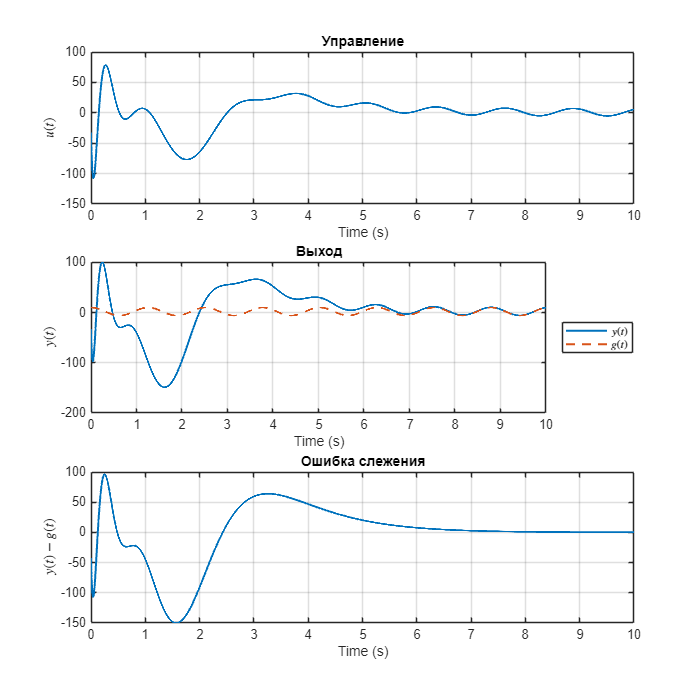

figure('Position', [0 0 700 700]);
m = 3; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.y, 'LineWidth', 1.5); hold on;
plot(out.g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(out.y-out.g, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/1_1_0_sim.png'], 'Resolution', 500);

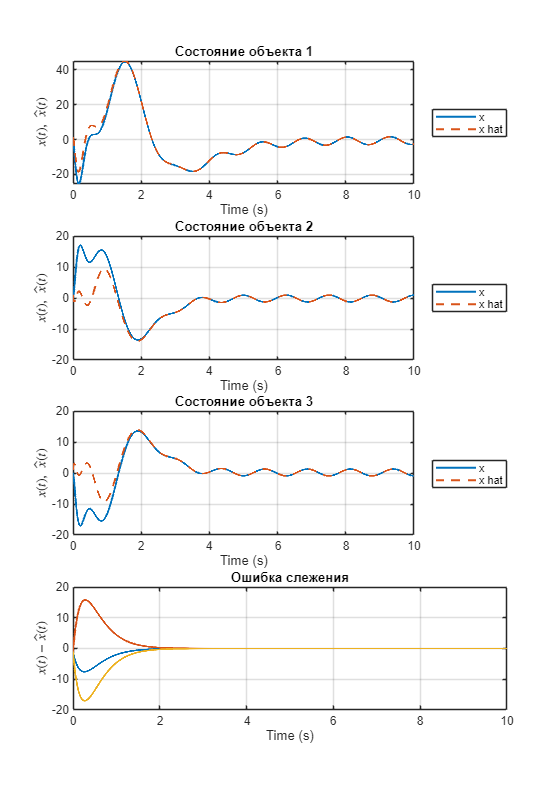

figure('Position', [0 0 700 1000]);
m = 4; % Number of rows
n = 1; % Number of columns

for i=1:3
    subplot(m, n, i);
    plot(out.tout, out.x.Data(:, i), 'LineWidth', 1.5); hold on;
    plot(out.tout, out.x_hat.Data(:, i), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$x(t),\ \hat x(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 4);
plot(out.x-out.x_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$x(t)-\hat x(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/1_1_1_sim.png'], 'Resolution', 500);

## Задание 2. Режекторная фильтрация: компенсация.

A = [3 5 4;-2 -4 -5;2 2 3];
B = [2;-1;1];
Bf = [-2   2 ; -2   0 ; 0   0];
C = [-2 -1 0];
D = 1;
Df = [4 1];
x0 = zeros(3, 1);

Gamma_f = [35  56  22  -42;
        -11  -17  -7  12;
        -6  -10  -5  10;
        11  18  6  -13];
Yf = [1 3;2 4;1 2;-1 -3]';
wf0 = ones(4, 1);

G = [1; 1; 1; 1];
controllable(Gamma_f, G);

Co =      1    71    31  -551
     1   -23   -49   119
     1   -11    79    59
     1    22    15  -262


rank_Co = 4

YES


Abar = [Gamma_f G*C; zeros(3, 4) A];
Bbar = [G*D; B];
Bfbar = [G*Df;Bf];
x0_bar = zeros(7, 1);

eig(Abar)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i


analyze_controllability(Abar, Bbar);

Eigenvalues of A:
   0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =  -35.0000 + 3.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  17.0000 + 3.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   5.0000 + 3.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  13.0000 + 3.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 + 3.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 + 3.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue 2.142730e-14 3.000000e+00i is controllable.


H =  -35.0000 - 3.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  17.0000 - 3.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   5.0000 - 3.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  13.0000 - 3.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 - 3.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 - 3.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue 2.142730e-14 -3.000000e+00i is controllable.


H =  -35.0000 + 1.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  17.0000 + 1.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   5.0000 + 1.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  13.0000 + 1.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue -1.870552e-14 1.000000e+00i is controllable.


H =  -35.0000 - 1.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  17.0000 - 1.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   5.0000 - 1.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  13.0000 - 1.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue -1.870552e-14 -1.000000e+00i is controllable.


H =  -33.0000 + 1.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  19.0000 + 1.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   7.0000 + 1.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  15.0000 + 1.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue 2 1.000000e+00i is controllable.


H =  -33.0000 - 1.0000i -56.0000 + 0.0000i -22.0000 + 0.0000i  42.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  11.0000 + 0.0000i  19.0000 - 1.0000i   7.0000 + 0.0000i -12.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   6.0000 + 0.0000i  10.0000 + 0.0000i   7.0000 - 1.0000i -10.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
 -11.0000 + 0.0000i -18.0000 + 0.0000i  -6.0000 + 0.0000i  15.0000 - 1.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

rank_H = 7

Eigenvalue 2 -1.000000e+00i is controllable.


H =   -37.0000  -56.0000  -22.0000   42.0000    2.0000    1.0000         0    1.0000
   11.0000   15.0000    7.0000  -12.0000    2.0000    1.0000         0    1.0000
    6.0000   10.0000    3.0000  -10.0000    2.0000    1.0000         0    1.0000
  -11.0000  -18.0000   -6.0000   11.0000    2.0000    1.0000         0    1.0000
         0         0         0         0   -5.0000   -5.0000   -4.0000    2.0000
         0         0         0         0    2.0000    2.0000    5.0000   -1.0000
         0         0         0         0   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 6

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


[AJ, BJ, P] = j_stuff_B(Abar, Bbar);

Вещественная жорданова форма матрицы A:
    -2     0     0     0     0     0     0
     0     2    -1     0     0     0     0
     0     1     2     0     0     0     0
     0     0     0     0    -1     0     0
     0     0     0     1     0     0     0
     0     0     0     0     0     0    -3
     0     0     0     0     0     3     0

Вещественная P:
    5.4308   -5.0912    9.9702   -1.4142    1.4142    2.8284         0
   -2.0462    3.4648   -4.3841    1.4142   -1.4142   -0.7071   -0.7071
   -4.3231   -1.2021    1.8385    1.4142    1.4142         0    1.4142
   -0.1846   -0.2475    2.8638    1.4142         0    1.4142         0
   -1.0000    0.7071   -0.7071         0         0         0         0
    1.0000   -1.4142         0         0         0         0         0
         0    1.4142         0         0         0         0         0

Вещественная P^{-1}:
    0.0000    0.0000    0.0000   -0.0000   -0.0000    1.0000    1.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000  

Aj = [
          2    -1     0     0     0     0
            1     2     0     0     0     0
           0     0     0    -1     0     0
            0     0     1     0     0     0
           0     0     0     0     0    -3
            0     0     0     0     3     0];
Bj =  [0.7071;   -2.1213;    1.9445;   13.7886;    3.1820;  -11.6673];
poles = [-1 -2 -3 -4 -5 -6];
Y1 = [1 1 1 1 1 1];
G1 = diag(poles);
observable(Y1, G1);

Ob =            1           1           1           1           1           1
          -1          -2          -3          -4          -5          -6
           1           4           9          16          25          36
          -1          -8         -27         -64        -125        -216
           1          16          81         256         625        1296
          -1         -32        -243       -1024       -3125       -7776


rank_Ob = 6

YES


cvx_begin sdp quiet;
    variable P1(6,6);
    Aj*P1-P1*G1 == Bj*Y1;
cvx_end;
Kj = -Y1*pinv(P1)

Kj =  -140.1853  -33.3227   -2.0279   -0.0766    2.5769   -0.0204


KJ = [0 Kj(1, 1) Kj(1, 2) Kj(1, 3) Kj(1, 4) Kj(1, 5) Kj(1, 6)];
K=KJ/P

K =    -3.4007   -6.7219   -3.3754    5.2626   53.3886   44.4828  -79.0596


eig(Abar+Bbar*K)

ans =    -5.9996
   -5.0167
   -1.0004
   -3.9680
   -3.0205
   -1.9952
   -2.0000


syms s
Cbar = [zeros(1,4) C] + D*K;
I = eye(7);
W = Cbar * (s*I - (Abar + Bbar*K))^(-1)*Bfbar + Df;
simpW = simplify(W)

$$simpW = \left(\begin{array}{cc} \frac{128\,\left(2475880078570760549798248448\,s^{7}-401340664449602579293441884160\,s^{6}+3569548500987906618907445690368\,s^{5}+4703617752742685085512952947800\,s^{4}+35470179922728861485732296358936\,s^{3}+83558177992339231532384051670347\,s^{2}+31903107301819654256334819684027\,s+78453219575149578339120350282634\right)}{79228162514264337593543950336\,s^{7}+2218379657248799271999405817856\,s^{6}+25512045195347797118444197337081\,s^{5}+155288090955672496704570879857296\,s^{4}+536300635219676540772286640184599\,s^{3}+1040435578605529806221344650266284\,s^{2}+1035359422750697583195258954881124\,s+399322510534960510004524320543984} & \frac{64\,\left(1237940039285380274899124224\,s^{6}+338776622072724558352891248640\,s^{5}-1846995940911533761596944809984\,s^{4}+3387766220727216592143653125594\,s^{3}-18582611952690176300302998465845\,s^{2}+3048989598654737336717325261117\,s-16734378071739804208889413741026\right)}{79228162514264337593543950336\,s^{6}+2059923332220270596812317917184\,s^{5}+21392198530907255924819561502713\,s^{4}+112503693893857984854931756851870\,s^{3}+311293247431960571062423126480859\,s^{2}+417849083741608664096498397304566\,s+199661255267480255002262160271992} \end{array}\right)$$

vpa(simpW, 4)

$$ans = \left(\begin{array}{cc} \frac{128.0\,\left(2.476e+27\,s^{7}-4.013e+29\,s^{6}+3.57e+30\,s^{5}+4.704e+30\,s^{4}+3.547e+31\,s^{3}+8.356e+31\,s^{2}+3.19e+31\,s+7.845e+31\right)}{7.923e+28\,s^{7}+2.218e+30\,s^{6}+2.551e+31\,s^{5}+1.553e+32\,s^{4}+5.363e+32\,s^{3}+1.04e+33\,s^{2}+1.035e+33\,s+3.993e+32} & \frac{64.0\,\left(1.238e+27\,s^{6}+3.388e+29\,s^{5}-1.847e+30\,s^{4}+3.388e+30\,s^{3}-1.858e+31\,s^{2}+3.049e+30\,s-1.673e+31\right)}{7.923e+28\,s^{6}+2.06e+30\,s^{5}+2.139e+31\,s^{4}+1.125e+32\,s^{3}+3.113e+32\,s^{2}+4.178e+32\,s+1.997e+32} \end{array}\right)$$

[num, den] = numden(simpW(1,1));
num = sym(num);
den = sym(den);
solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i}\\ 3.0\,\mathrm{i}\\ -3.0\,\mathrm{i}\\ -2.0\\ 11.54\\ 152.6 \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -2.0\\ -1.0\\ -2.971\\ -4.407-0.05571\,\mathrm{i}\\ -4.407+0.05571\,\mathrm{i}\\ -6.572\\ -6.642 \end{array}\right)$$

[num, den] = numden(simpW(1,2));
num = sym(num);
den = sym(den);
solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -279.0\\ 5.383\\ -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i}\\ 3.0\,\mathrm{i}\\ -3.0\,\mathrm{i} \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -1.0\\ -2.971\\ -4.407-0.05571\,\mathrm{i}\\ -4.407+0.05571\,\mathrm{i}\\ -6.572\\ -6.642 \end{array}\right)$$

I=eye(4);
E = simpW*(Yf*(s*I-Gamma_f)^(-1)*wf0);
simpE = simplify(E);
vpa(simpE, 4)

$$ans = -\frac{64.0\,\left(-2.228e+28\,s^{10}+3.593e+29\,s^{9}-3.23e+31\,s^{8}+6.739e+31\,s^{7}-2.448e+32\,s^{6}+1.009e+33\,s^{5}+1.941e+33\,s^{4}+4.248e+33\,s^{3}+1.536e+34\,s^{2}+3.307e+33\,s+1.32e+34\right)}{7.923e+28\,s^{11}+2.218e+30\,s^{10}+2.63e+31\,s^{9}+1.775e+32\,s^{8}+7.921e+32\,s^{7}+2.613e+33\,s^{6}+6.628e+33\,s^{5}+1.22e+34\,s^{4}+1.518e+34\,s^{3}+1.336e+34\,s^{2}+9.318e+33\,s+3.594e+33}$$

var = vpa(limit(s*simpE,s,0), 4)

$$var = 0.0$$

model_name = 'task3';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(10));

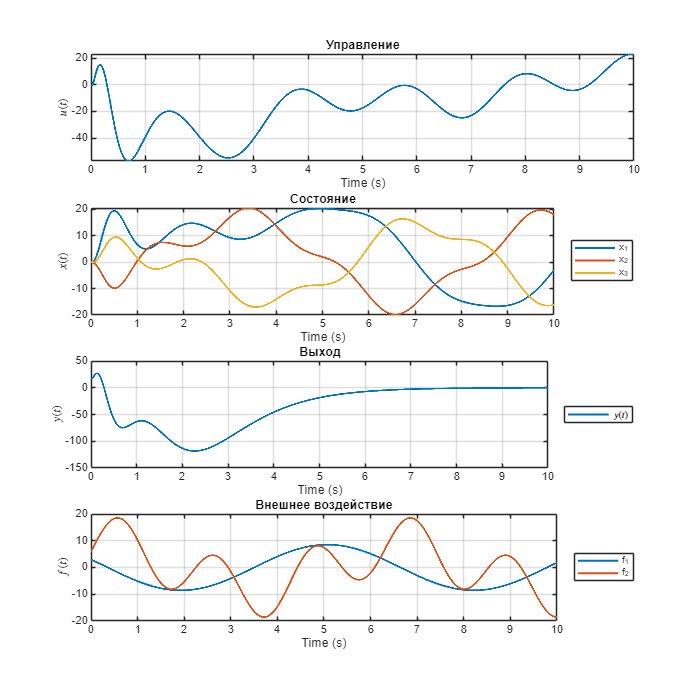

figure('Position', [0 0 700 700]);
m = 4; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
ylabel('$x(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(out.y, 'LineWidth', 1.5); hold on;
legend({'$y(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(out.f, 'LineWidth', 1.5); hold on;
title('Внешнее воздействие');
xlabel('Time (s)');
ylabel('$f(t)$', 'Interpreter', 'latex');
legend({'f_1', 'f_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_0_sim.png'], 'Resolution', 500);

observable(C, A);

Ob =     -2    -1     0
    -4    -6    -3
    -6    -2     5


rank_Ob = 3

YES


eig(A)

ans =    2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i


G1 = diag([-3, -4, -5]);
Y1 = [1; 1; 1];
controllable(G1, Y1)

Co =      1    -3     9
     1    -4    16
     1    -5    25


rank_Co = 3

YES


cvx_begin sdp quiet;
    variable Q1(3,3);
    Q1*A-G1*Q1 == Y1*C;
cvx_end;
L = -inv(Q1)*Y1

L =   -18.5294
   51.0588
  -51.4118


eig(A+L*C)

ans =    -5.0000
   -4.0000
   -3.0000


Kw = [K(1, 1) K(1, 2) K(1, 3) K(1, 4)];
Kx = [K(1, 4) K(1, 5) K(1, 6)];
Ktil = [Kw zeros(1,3) Kx];
Atil = [Gamma_f zeros(4, 3) G*C;
        zeros(3,4) A zeros(3,3);
        zeros(3,4) -L*C A+L*C];
Btil = [G*D; B; B];
Bftil = [G*Df; zeros(6, 2)];
Ctil = [D*Kw zeros(1,3) C+D*Kx];

syms s
I = eye(10);
W = Ctil * (s*I - (Atil + Btil*Ktil))^(-1)*Bftil + Df;
simpW = simplify(W)

$$simpW = \begin{array}{l} \left(\begin{array}{cc} \frac{256\,\sigma_{2}}{\sigma_{1}} & \frac{64\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=6669420593848348311575526262158145567108752659743036669952\,s^{9}+167906696899631318763497401364683191588637472349534096982016\,s^{8}-953151492557930544295292964374507383439889263665130755850240\,s^{7}-14707703036204890576884918494852597939510532433390680336760832\,s^{6}-15450502407657762878032286534442119320764526217321599900468971\,s^{5}+119884145565586020380469286022261812850908797532618741779643105\,s^{4}+203811064252511396592573510572620296581772224688015898298587587\,s^{3}+472691061702344798743404956554133422098157991848460949367147881\,s^{2}+1110674588930362855805508295597687710435596425990658949805977222\,s-1217373363227127492849615979510318303459418085946581525061737480\\ \sigma_{2}=104209696778880442368367597846221024486074260308484947968\,s^{9}-2875051947924470549484585288906727983217851193978926399488\,s^{8}-30512235066873101412070357456142966061510923287299706847232\,s^{7}-59744065072423725430234807238999373571865957330246229295104\,s^{6}+51428168983346832951573551395170258636795105677691876016128\,s^{5}+447466992215816543092760814865336082907434599135794972848600\,s^{4}+3376347032277538230010740120028037408438442193303203915216371\,s^{3}+7553837246450528383591709339571042032628357299640260768344452\,s^{2}+3294302418530571959200773873822569142216172603599308084297955\,s+7049501241110454046346667162601132321936321693842856510123470 \end{array}$$

vpa(simpW, 4)

$$ans = \begin{array}{l} \left(\begin{array}{cc} \frac{256.0\,\sigma_{2}}{\sigma_{1}} & \frac{64.0\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=6.669e+57\,s^{9}+1.679e+59\,s^{8}-9.532e+59\,s^{7}-1.471e+61\,s^{6}-1.545e+61\,s^{5}+1.199e+62\,s^{4}+2.038e+62\,s^{3}+4.727e+62\,s^{2}+1.111e+63\,s-1.217e+63\\ \sigma_{2}=1.042e+56\,s^{9}-2.875e+57\,s^{8}-3.051e+58\,s^{7}-5.974e+58\,s^{6}+5.143e+58\,s^{5}+4.475e+59\,s^{4}+3.376e+60\,s^{3}+7.554e+60\,s^{2}+3.294e+60\,s+7.05e+60 \end{array}$$

[num, den] = numden(simpW(1,1));
num = sym(num);
den = sym(den);
solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i}\\ 3.0\,\mathrm{i}\\ -3.0\,\mathrm{i}\\ -3.0\\ 3.468\\ -4.0\\ -5.0\\ 36.12 \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} 0.7504\\ 0.02057-2.049\,\mathrm{i}\\ 0.02057+2.049\,\mathrm{i}\\ -3.0\\ 3.431\\ -4.0\\ -5.0\\ 10.2\\ -27.6 \end{array}\right)$$

[num, den] = numden(simpW(1,2));
num = sym(num);
den = sym(den);
solution = solve(num, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i}\\ 3.0\,\mathrm{i}\\ -3.0\,\mathrm{i}\\ -3.0\\ 3.468\\ -4.0\\ -5.0\\ 36.12 \end{array}\right)$$

solution = solve(den, s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} 0.7504\\ 0.02057-2.049\,\mathrm{i}\\ 0.02057+2.049\,\mathrm{i}\\ -3.0\\ 3.431\\ -4.0\\ -5.0\\ 10.2\\ -27.6 \end{array}\right)$$

I=eye(4);
E = simpW*(Yf*(s*I-Gamma_f)^(-1)*wf0);
simpE = simplify(E);
vpa(simpE, 4)

$$ans = \frac{64.0\,\left(1.876e+57\,s^{12}-5.165e+58\,s^{11}-5.335e+59\,s^{10}-1.642e+60\,s^{9}-3.901e+60\,s^{8}+4.52e+60\,s^{7}+8.418e+61\,s^{6}+2.071e+62\,s^{5}+5.645e+62\,s^{4}+6.948e+62\,s^{3}-1.152e+63\,s^{2}+4.938e+62\,s-1.628e+63\right)}{6.669e+57\,s^{13}+1.679e+59\,s^{12}-8.865e+59\,s^{11}-1.303e+61\,s^{10}-2.492e+61\,s^{9}-2.568e+61\,s^{8}+4.073e+61\,s^{7}+1.539e+63\,s^{6}+3.01e+63\,s^{5}+4.588e+63\,s^{4}+1.294e+64\,s^{3}-7.92e+63\,s^{2}+9.996e+63\,s-1.096e+64}$$

var = vpa(limit(s*simpE,s,0), 4)

$$var = 0.0$$

L =  -150.5294
  333.0588
 -351.4118


ans =   -15.0000
  -10.0000
   -5.0000


model_name = 'task4';
load_system(model_name);
out = sim(model_name, 'StopTime', num2str(1));

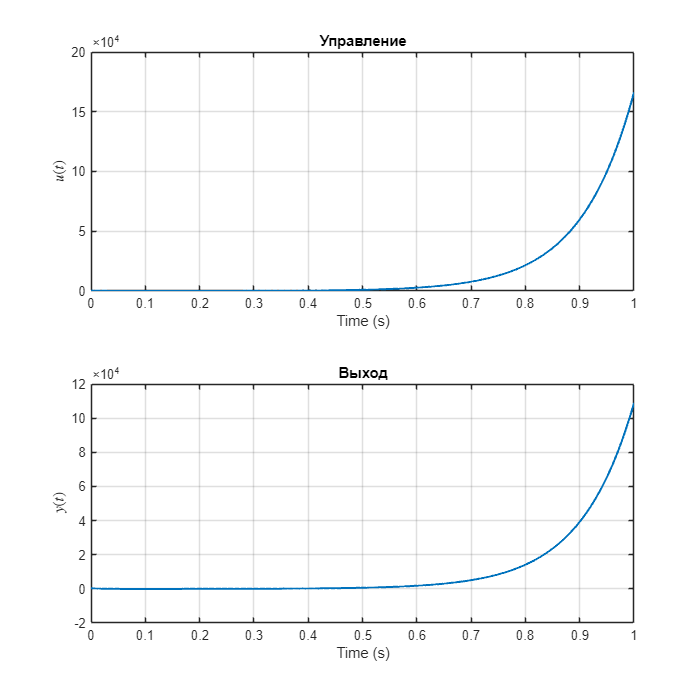

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(out.u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(out.y, 'LineWidth', 1.5); hold on;
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_1_0_sim.png'], 'Resolution', 500);

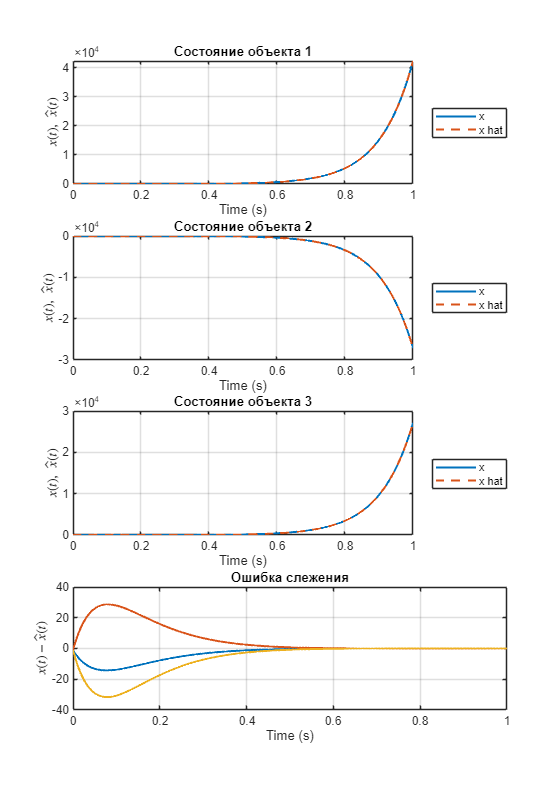

figure('Position', [0 0 700 1000]);
m = 4; % Number of rows
n = 1; % Number of columns

for i=1:3
    subplot(m, n, i);
    plot(out.tout, out.x.Data(:, i), 'LineWidth', 1.5); hold on;
    plot(out.tout, out.x_hat.Data(:, i), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$x(t),\ \hat x(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 4);
plot(out.x-out.x_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$x(t)-\hat x(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_1_1_sim.png'], 'Resolution', 500);

A = [3 5 4;-2 -4 -5;2 2 3];
B = [2;-1;1];
Bf = [-2   2 ; -2   0 ; 0   0];
C = [-2 -1 0];
D = 1;
Df = [4 1];
Gamma_f = [35  56  22  -42;
        -11  -17  -7  12;
        -6  -10  -5  10;
        11  18  6  -13];
Yf = [1 3;2 4;1 2;-1 -3]';
wf0 = [1; 1; 1; 1];                                     % 4x1
x0 = [0; 0; 0];                                         % 3x1

% Матрицы системы
G = [1; 1; 1; 1]; % Матрица G для внутренней модели

% Расширенная модель
Abar = [Gamma_f, G*C; zeros(3,4), A];
Bbar = [G*D; B];
Bfbar = [G*Df; Bf];

% Определение матриц системы
[Q, R] = qr(U); % QR-разложение матрицы управляемости
T = Q(:, 1:r);  % Базис управляемого подпространства (первые r столбцов)

% Дополнение базиса до полного пространства
T_full = Q; % Полная ортогональная матрица

% Преобразование системы
A_transformed = T_full \ Abar * T_full; % T_full^(-1) * A_bar * T_full
B_transformed = T_full \ Bbar;          % T_full^(-1) * B_bar

% Извлечение управляемой подсистемы
A_c = A_transformed(1:r, 1:r); % Матрица A для управляемой части
B_c = B_transformed(1:r);      % Матрица B для управляемой части



% Синтез регулятора

poles = [-1 -2 -3 -4 -5 -6];
Y = [1 1 1 1 1 1];
G1 = diag(poles);

cvx_begin sdp quiet;
    variable P(6,6);
    A_c*P-P*G1 == B_c*Y;
cvx_end;
K_c = -Y*inv(P);

T_inv = inv(T_full); % Обратная матрица преобразования
T_c_inv = T_inv(1:size(A_c,1), :); % Строки, соответствующие z_c
K = K_c * T_c_inv % Регулятор для исходной системы

K =    -3.4007   -6.7218   -3.3753    5.2626   53.3882   61.7706  -61.7706


Cbar = [zeros(1, 4) C] - D*K;
Kw = K(:,1:4); % Для e_w
Kx = K(:,5:7); % Для x

Yo = [1;1;1];
G1 = diag([-3, -4, -5]);
cvx_begin quiet;
    variable Q(3,3);
    G1*Q-Q*A == Yo*C;
cvx_end;
L = inv(Q)*Yo

L =   -18.5294
   51.0588
  -51.4118


eig(A + L*C)

ans =    -5.0000
   -4.0000
   -3.0000



tspan = [0 20];
initial = [wf0; zeros(4,1); x0; ones(3,1)]; % [w_g; e_w; x, hat_x]

u = @(t, z) (Kw*z(5:8) + Kx*z(12:14));
% ode_func = @(t, z) [Gamma_f*z(1:4); ... % w_f
%                     Gamma_f*z(5:8) + G*(Df*Yf*z(1:4) + C*z(9:11) + D*u(t, z));
%                     A*z(9:11) + B*u(t, z) + Bf * Yf*z(1:4);... % x
%                     A*z(12:14) + B*u(t, z) + Bf * Yf*z(1:4)  + L * (C * z(12:14) - C * z(9:11))]; % x_hat
ode_func = @(t, z) [Gamma_f*z(1:4); ... % w_f
                    Gamma_f*z(5:8) + G*(Df*Yf*z(1:4) + C*z(9:11) + D*u(t, z));
                    A*z(9:11) + B*u(t, z) + Bf * Yf*z(1:4);... % x
                    A*z(12:14) + B*u(t, z) + L * (C * z(12:14) - C * z(9:11))]; % x_hat

[t, z] = ode45(ode_func, tspan, initial);

% Вычисление сигналов
f = Yf*z(:,1:4)';
u = Kw*z(:, 5:8)'+ Kx*z(:, 12:14)';
y = C*z(:,9:11)' + D * u + Df * f;
x = z(:, 9:11)';
x_hat = z(:, 12:14)';

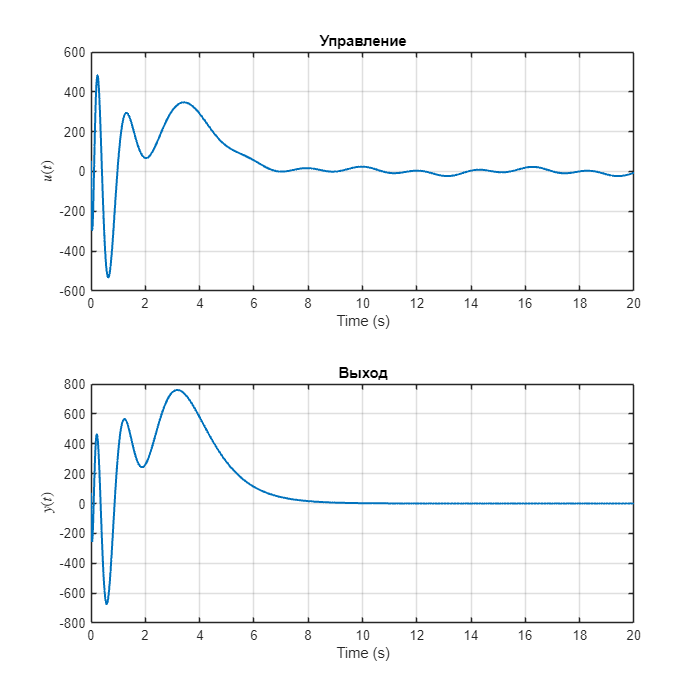

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(t, y, 'LineWidth', 1.5); hold on;
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_1_0_sim.png'], 'Resolution', 500);

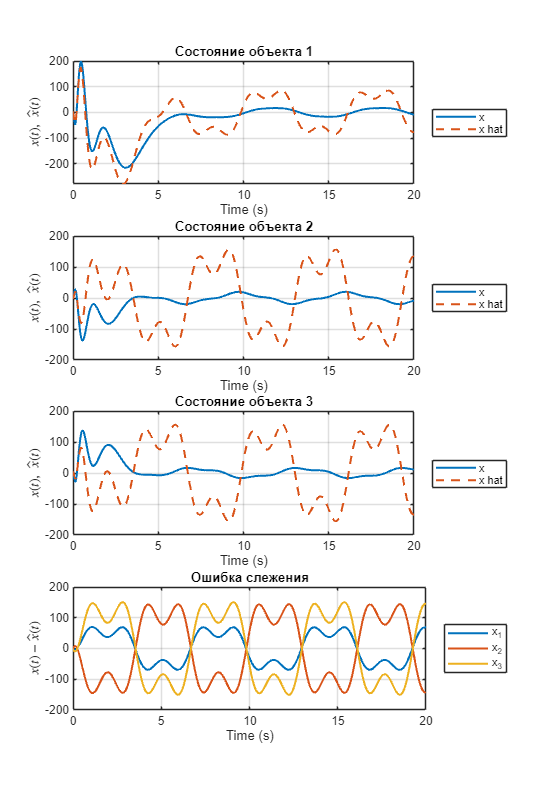

figure('Position', [0 0 700 1000]);
m = 4; % Number of rows
n = 1; % Number of columns

for i=1:3
    subplot(m, n, i);
    plot(t, x(i, :), 'LineWidth', 1.5); hold on;
    plot(t, x_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$x(t),\ \hat x(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 4);
plot(t, x - x_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$x(t)-\hat x(t)$', 'Interpreter', 'latex');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_1_1_sim.png'], 'Resolution', 500);

## Задание 3. Режекторная фильтрация: Все разом.

A = [3 5 4;-2 -4 -5;2 2 3];
B = [2;-1;1];
Bf = [-2   2 ; -2   0 ; 0   0];
C = [-2 -1 0];
D = 1;
Df = [4 1];
x0 = zeros(3, 1);
Gamma_f = [35  56  22  -42;
        -11  -17  -7  12;
        -6  -10  -5  10;
        11  18  6  -13];
Yf = [1 3;2 4;1 2;-1 -3]';
wf0 = ones(4, 1);
Gamma_g = [0 5 0;-5 0 0;0 0 0];
Yg = [8 0 2];
wg0 = [1; 0; 1];
Gamma_w = [Gamma_f zeros(4,3); zeros(3,4) Gamma_g];
Ygbar = [zeros(1,4) Yg];
Yfbar = [Yf zeros(2,3)];
w0 = [wf0; wg0];
e0_bar = [w0; x0];


% Матрицы системы

G = [1; 1; 1; 1; 1; 1; 1]; % Матрица G для внутренней модели

% Расширенная модель
Abar = [Gamma_w, -G*C; zeros(3,7), A];
Bbar = [-G*D; B];
Bfbar = [-G*Df; Bf];
Gbar = [G; zeros(3, 1)];
% Определение матриц системы


% Вычисление матрицы управляемости
n = size(Abar, 1); % Размерность системы
U = ctrb(Abar, Bbar); % Матрица управляемости

% Проверка ранга управляемости
r = rank(U) % Ранг матрицы управляемости

r = 9


eig(Abar)

ans =    0.0000 + 0.0000i
  -0.0000 + 3.0000i
  -0.0000 - 3.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 + 5.0000i
   0.0000 - 5.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i


% Нахождение базиса для управляемого подпространства
[Q, R] = qr(U); % QR-разложение матрицы управляемости
T = Q(:, 1:r);  % Базис управляемого подпространства (первые r столбцов)

% Дополнение базиса до полного пространства
T_full = Q; % Полная ортогональная матрица

% Преобразование системы
A_transformed = T_full \ Abar * T_full; % T_full^(-1) * A_bar * T_full
B_transformed = T_full \ Bbar;          % T_full^(-1) * B_bar

% Извлечение управляемой подсистемы
A_c = A_transformed(1:r, 1:r); % Матрица A для управляемой части
B_c = B_transformed(1:r);      % Матрица B для управляемой части



% Синтез регулятора

poles = [-1 -3 -4 -5 -6 -7 -8 -9 -10];
Y = [1 1 1 1 1 1 1 1 1];
G1 = diag(poles);


% P = sylvester(Abar, G1, Bbar*Y)
cvx_begin sdp quiet;
    variable P(9,9);
    A_c*P-P*G1 == B_c*Y;
cvx_end;
K_c = -Y*inv(P);

T_inv = inv(T_full); % Обратная матрица преобразования
T_c_inv = T_inv(1:size(A_c,1), :); % Строки, соответствующие z_c
K = K_c * T_c_inv % Регулятор для исходной системы

K = 1.0e+03 *

    0.8901    1.3779    0.6265   -1.1177    0.1892    0.0416    0.6720    4.3587    3.0474   -3.0474


% poles = [-1 -2 -3 -4 -5 -6];
% K = place(Abar, Bbar, poles)
Cbar = [zeros(1, 7) C] - D*K;
Kw = K(:,1:7); % Для e_w
Kx = K(:,8:10); % Для x

A_cl = Abar + Bbar * K;
eig_A_cl = eig(A_cl)

eig_A_cl =   -10.0000
   -9.0001
   -7.9998
   -7.0002
   -1.0000
   -5.9999
   -5.0000
   -4.0000
   -3.0000
   -2.0000


% disp('Собственные числа замкнутой системы:');
% disp(eig_A_cl);
% C_y = [-D*Kw, C - D*Kx]; % Выход y = C_y * e



% Моделирование
tspan = [0 10];
initial = [wf0; wg0; zeros(7,1); x0]; % [w_f; wg; x_w; x]
u = @(t, z) (Kw*z(8:14) + Kx*z(15:17));
% ode_func = @(t, z) [Gamma_g*z(1:3); ... % w_g
%                     Gamma_g*z(4:6) + G*(Yg*z(1:3) - C*z(7:9) - D*(Kw*z(4:6) + Kx*z(7:9))); ... % e_w
%                     A*z(7:9) + B*(Kw*z(4:6) + Kx*z(7:9))]; % x
ode_func = @(t, z) [Gamma_f*z(1:4); ... % w_f
                    Gamma_g*z(5:7);...
                    Gamma_w*z(8:14) + G*(Yg*z(5:7)-Df*Yf*z(1:4) - C*z(15:17) - D*u(t, z)); ... % x_w
                    A*z(15:17) + B*u(t, z) + Bf *Yf*z(1:4)]; % x
% ode_func = @(t, z) [Gamma_f*z(1:4); ... % w_f
%                     (Abar+Bbar*K)*z(5:11) + Bfbar*Yf * z(1:4)]; % x
[t, z] = ode45(ode_func, tspan, initial);

% Вычисление сигналов
f = Yf*z(:,1:4)';
g = Yg * z(:, 5:7)';
u = K*z(:, 8:17)';
% y = Cbar*z(:,5:11)';
y = C*z(:,15:17)' + D * u + Df * f;
x = z(:, 15:17)';
epsilon = g - y;

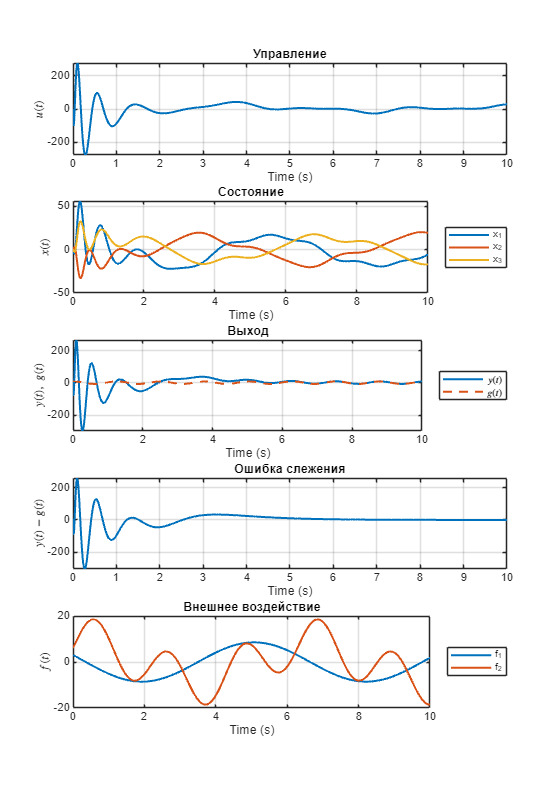

figure('Position', [0 0 700 1000]);
m = 5; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(t, x, 'LineWidth', 1.5); hold on;
title('Состояние');
xlabel('Time (s)');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
ylabel('$x(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(t, y, 'LineWidth', 1.5); hold on;
plot(t, g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t),\ g(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(t, y-g, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 5);
plot(t, f, 'LineWidth', 1.5); hold on;
title('Внешнее воздействие');
xlabel('Time (s)');
ylabel('$f(t)$', 'Interpreter', 'latex');
legend({'f_1', 'f_2'}, 'Location', 'eastoutside');
grid on;

exportgraphics(gcf, ['figs/3_0_sim.png'], 'Resolution', 500);

tspan = [0 10];
initial = [wf0; wg0; zeros(7,1); x0; ones(3,1)]; % [w_g; e_w; x, hat_x]

u = @(t, z) (Kw*z(8:14) + Kx*z(18:20));
ode_func = @(t, z) [Gamma_f*z(1:4); ... % w_f
                    Gamma_g*z(5:7);...
                    Gamma_w*z(8:14) + G*(Yg*z(5:7)-Df*Yf*z(1:4) - C*z(15:17) - D*u(t, z)); ... % x_w
                    A*z(15:17) + B*u(t, z) + Bf * Yf*z(1:4);... % x
                    A*z(18:20) + B*u(t, z) + L * (C * z(18:20) - C * z(15:17))]; % x_hat

[t, z] = ode45(ode_func, tspan, initial);

% Вычисление сигналов
f = Yf*z(:,1:4)';
g = Yg * z(:, 5:7)';
u = Kw*z(:, 8:14)' + Kx * z(:, 18:20)';
y = C*z(:,15:17)' + D * u + Df * f;
epsilon = g - y;
x = z(:, 15:17)';
x_hat = z(:, 18:20)';

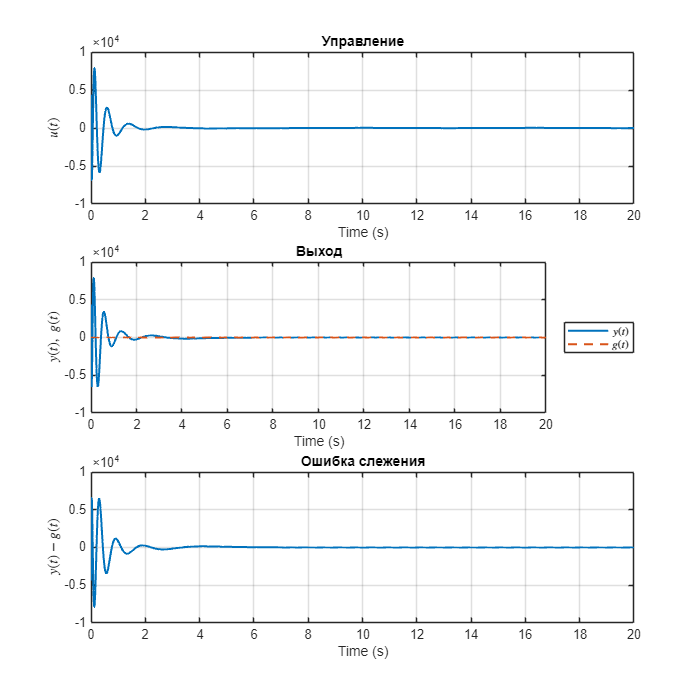

figure('Position', [0 0 700 700]);
m = 3; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(t, y, 'LineWidth', 1.5); hold on;
plot(t, g, '--', 'LineWidth', 1.5);
legend({'$y(t)$', '$g(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t),\ g(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(t, epsilon, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$y(t)-g(t)$', 'Interpreter', 'latex');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/3_1_0_sim.png'], 'Resolution', 500);

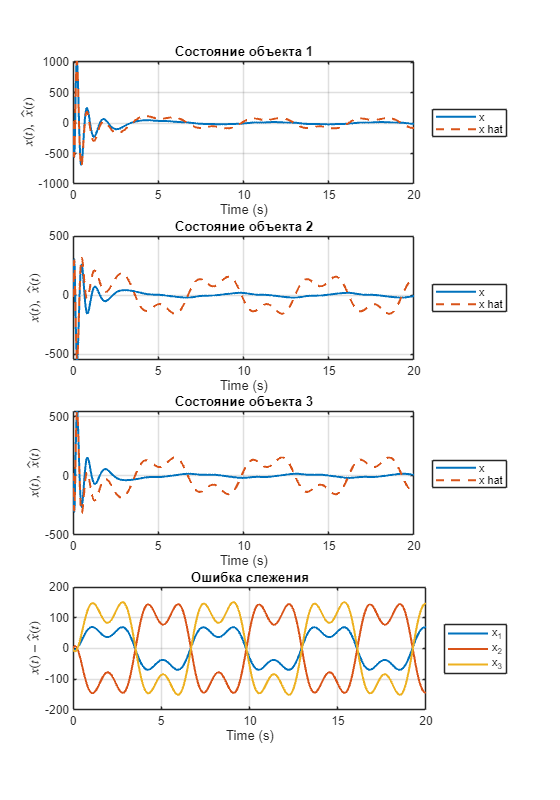

figure('Position', [0 0 700 1000]);
m = 4; % Number of rows
n = 1; % Number of columns

for i=1:3
    subplot(m, n, i);
    plot(t, x(i, :), 'LineWidth', 1.5); hold on;
    plot(t, x_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$x(t),\ \hat x(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 4);
plot(t, x - x_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения');
xlabel('Time (s)');
ylabel('$x(t)-\hat x(t)$', 'Interpreter', 'latex');
legend({'x_1', 'x_2', 'x_3'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/3_1_1_sim.png'], 'Resolution', 500);